# Simulate Multiple Fixed-Wing UAVs in Simulink Using System Objects

This example shows how to simulate a multiple-UAV in a waypoint-following mission in Simulink® by using System objects to implement multiple instances. In addition, this example shows how to visualize multiple UAVs and waypoints using the UAV Animation block. 

To learn more about how to use System objects, see [What Are System Objects?](https://www.mathworks.com/help/matlab/matlab_prog/what-are-system-objects.html) and [System Design in Simulink Using System Objects](https://www.mathworks.com/help/simulink/ug/system-design-in-simulink-using-system-objects.html). 

### Create UAV Waypoints

Create waypoints for five UAVs. First, define the number of UAVs in the simulation.

numUAVs = 5;

In this example, each UAV has 10 waypoints. All UAVs first fly in a straight line, followed by a semicircular U-turn as illustrated in this image. 

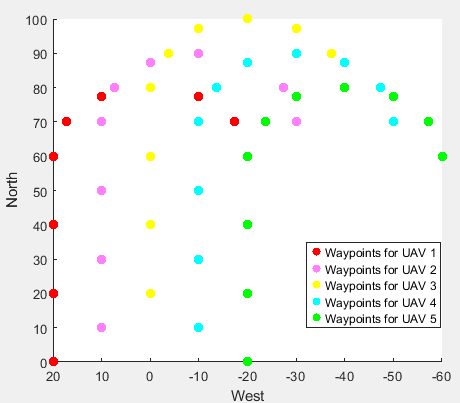

Create an empty array to store all the waypoints.

wayPoints = zeros(10,3,numUAVs);

Create waypoints for each UAV in the north-east-down (NED) frame, in meters.

wayPoints1 = [0     -20    0; ...
              20    -20    0; ...
              40    -20    0; ...
              60    -20    0; ...
              70    -17.32 0; ...
              77.32 -10    0; ...
              80     0     0; ...
              77.32  10    0; ...
              70     17.32 0; ...
              60     20    0];

wayPoints2 = [10    -10    0; ...
              30    -10    0; ...
              50    -10    0; ...
              70    -10    0; ...
              80    -7.32  0; ...
              87.32  0     0; ...
              90     10    0; ...
              87.32  20    0; ...
              80     27.32 0; ...
              70     30    0];

wayPoints3 = [20     0     0; ... 
              40     0     0; ... 
              60     0     0; ... 
              80     0     0; ...
              90     3.68  0; ...
              97.32  10    0; ...
              100    20    0; ...
              97.32  30    0; ...
              90     37.32 0; ...
              80     40    0];

wayPoints4 = [10     10    0; ...
              30     10    0; ...
              50     10    0; ...
              70     10    0; ...
              80     13.68 0; ...
              87.32  20    0; ...
              90     30    0; ...
              87.32  40    0; ...
              80     47.32 0; ...
              70     50    0];

wayPoints5 = [0      20    0; ...
              20     20    0; ...
              40     20    0; ...
              60     20    0; ...
              70     23.68 0; ...
              77.32  30    0; ...
              80     40    0; ...
              77.32  50    0; ...
              70     57.32 0; ...
              60     60    0];

Populate the waypoints array.

wayPoints(:,:,1) = wayPoints1;
wayPoints(:,:,2) = wayPoints2;
wayPoints(:,:,3) = wayPoints3;
wayPoints(:,:,4) = wayPoints4;
wayPoints(:,:,5) = wayPoints5;

### Creates Bus Signal Definitions

Create bus signal definitions for the state, control, and environment signals for the guidance models, and store them to the `busSignal.sldd` data dictionary by using the `exampleHelperMultiUAVSetupScript` helper function.

exampleHelperMultiUAVSetupScript

### Model Overview

The `formationFlightSimulation.slx` Simulink model consists of these main parts:

- `Multi-Instance Waypoint Follower` — MATLAB System block that implements multiple instances of the `uavWaypointFollower` object™ from UAV Toolbox, providing guidance logic for all the UAVs.

- `Multi-Instance Heading Controller` - MATLAB Function block that calculates the heading control input for all UAVs.

- `Multi-Instance Guidance Model` - Subsystem that implements multiple instances of the `fixedwing` guidance model object from UAV Toolbox, providing a low-fidelity model for all the UAVs.

- `UAV Animation` Block — Animates the flight path, waypoints, and lookahead points of all UAVs.

The `Multi-Instance Waypoint Follower` block uses the `multiWaypointFollower` System object to implement multiple instances of the `uavWaypointFollower` object. Similarly, the `Multi-Instance Guidance Model` block uses the `multiFixedwingDerivative` System object to the implement multiple instances of the `fixedwing` guidance model object.

Both System objects have multiple defined object functions and properties. The properties that appear on their MATLAB System block masks are nontunable, which means you cannot change them once you instantiate the objects. Some of the important methods of the system object are:

- resetImpl - This method initializes multiple `uavWaypointFollower` objects, with appropriate properties, once the system object has been initialized.

- stepImpl - This method loops over each of the `uavWaypointFollower` objects and computes the look-ahead point and desired course for each of them.

Note: For this example, the `Multi-Instance Waypoint Follower` and `Multi-Instance Guidance Model` blocks support simulation using only interpreted execution.

Open the `formationFlightSimulation.slx` Simulink model. To set the properties of the waypoint follower for each UAV, open the mask for the `Multi-Instance Waypoint Follower` block. Select **Source code** to look at the underlying System object. 

open_system("formationFlightSimulation")

#### 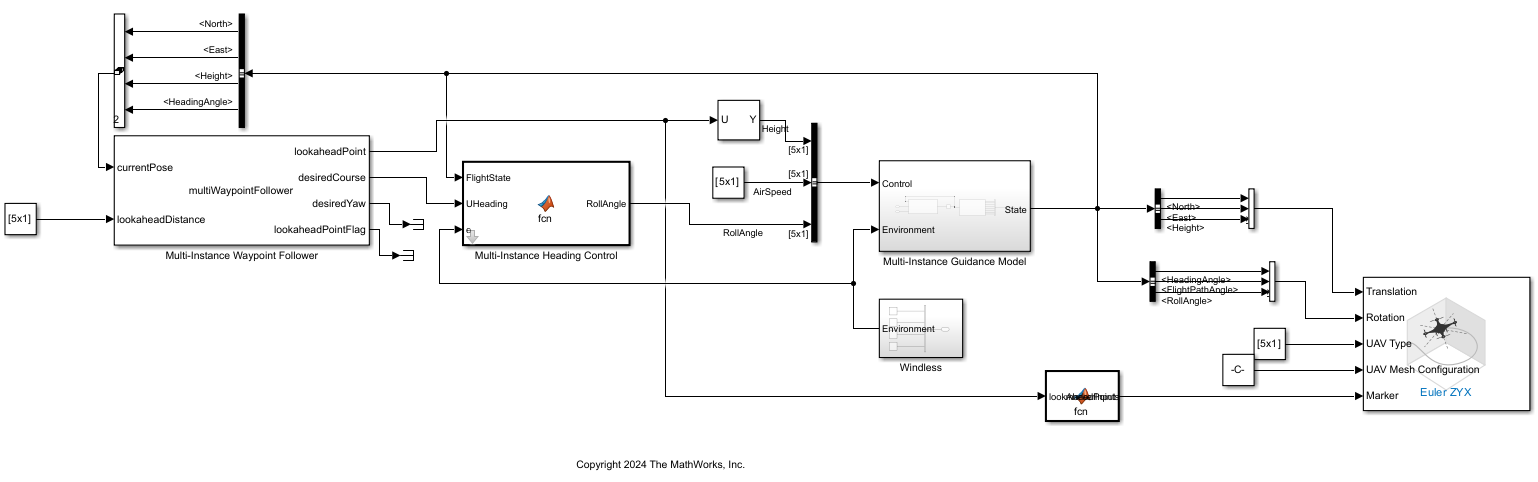

### Run Simulation

Run the Simulink model to simulate the formation flight. The UAV Animation block generates an animation of all the UAVs in formation, with their corresponding trajectories, waypoints, and look-ahead points.

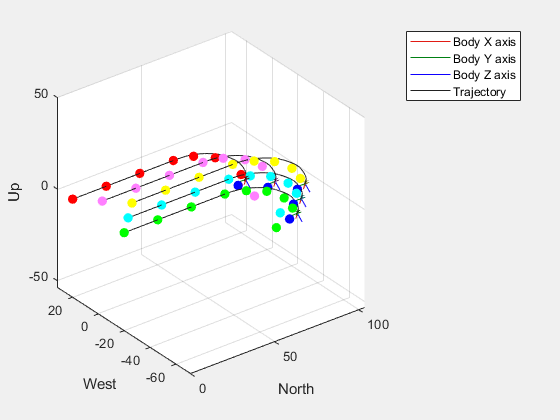

sim("formationFlightSimulation");

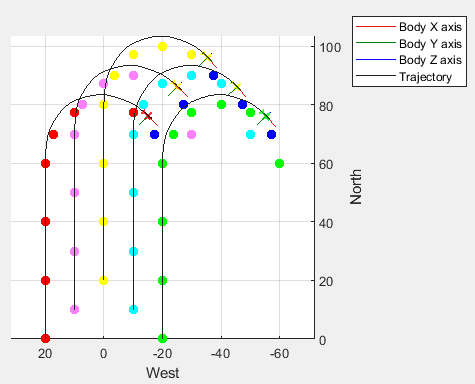

*Copyright 2024 The MathWorks, Inc.*